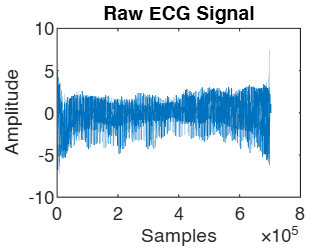

% Load the CSV data
ecg = readmatrix('ecg.csv'); 
ecg = ecg(:);                 

% Set the sampling frequency
fs = 500; 

% Plotting raw ECG
figure;
plot(ecg);
title('Raw ECG Signal');
xlabel('Samples');
ylabel('Amplitude');

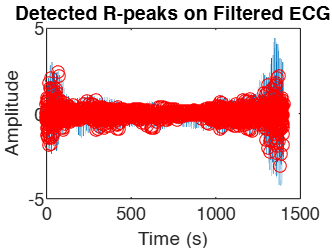


% Bandpass filtering
ecg_filtered = bandpass(ecg, [0.5 45], fs);

% Differentiating the signal
diff_ecg = diff(ecg_filtered);
diff_ecg(end+1) = diff_ecg(end);  

% Squaring the signal
squared_ecg = diff_ecg .^ 2;

% Moving average filter
window_size = round(0.150 * fs);
integrated_ecg = movmean(squared_ecg, window_size);

% Peak detection
[~, locs] = findpeaks(integrated_ecg, ...
    'MinPeakHeight', 0.002, ...
    'MinPeakDistance', round(0.4 * fs));

% Plot final result
t = (1:length(ecg)) / fs;
figure;
plot(t, ecg_filtered); hold on;
plot(t(locs), ecg_filtered(locs), 'ro');
title('Detected R-peaks on Filtered ECG');
xlabel('Time (s)');
ylabel('Amplitude');

% R-R Intervals (time between successive R-peaks)
rr_intervals = diff(locs) / fs;

% Displaying a few sample R-R intervals
disp('Sample R-R intervals (in seconds):');

Sample R-R intervals (in seconds):


disp(rr_intervals(1:10));

    0.6140
    0.6600
    0.5720
    0.4060
    0.7040
    0.4620
    0.4780
    0.4500
    0.4120
    0.4900



% Heart rate from R-R intervals (bpm)
heart_rate = 60 ./ rr_intervals;

% Displaying a few sample heart rates
disp('Sample heart rates (in bpm):');

Sample heart rates (in bpm):


disp(heart_rate(1:10));

   97.7199
   90.9091
  104.8951
  147.7833
   85.2273
  129.8701
  125.5230
  133.3333
  145.6311
  122.4490



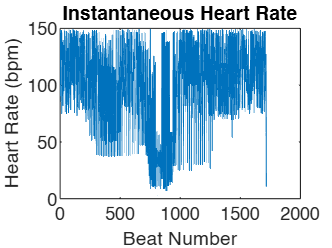

figure;
plot(heart_rate);
title('Instantaneous Heart Rate');
xlabel('Beat Number');
ylabel('Heart Rate (bpm)');

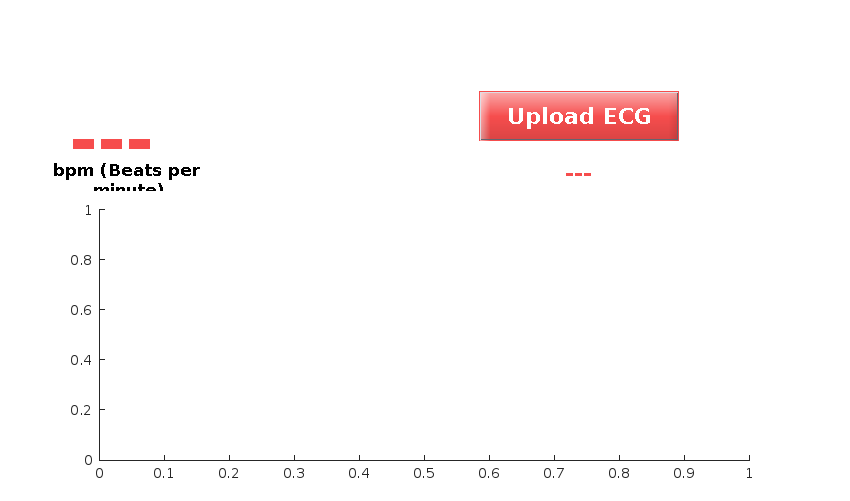

ecg_gui_arrhythmia